% (x*y+sin(y))*dx+(0.5*x^2+x*cos(y))*dy=0

% 1)
clear
% y'==-(x*y+sin(y))/(0.5*x^2+x*cos(y))
syms x y(x) C
eqn=(x*y+sin(y))+(0.5*x^2+x*cos(y))*diff(y,x)

$$eqn(x) = \left(x\,\cos\left(y\left(x\right)\right)+\frac{x^{2}}{2}\right)\,\frac{\partial }{\partial x}y\left(x\right)+\sin\left(y\left(x\right)\right)+x\,y\left(x\right)$$

ySol=dsolve(eqn)

$$ySol = \mathrm{solve}\left(\frac{y\,x^{2}}{2}+\sin\left(y\right)\,x+C_{30},y\right)$$

% solve(2*sin(y) + x*y == -C4/x, y)
eq1= 2*sin(y)*x + x^2*y == C

$$eq1(x) = x^{2}\,y\left(x\right)+2\,x\,\sin\left(y\left(x\right)\right)=C$$


% 2)
syms x y dx dy C
eq1=(x*y+sin(y))*dx+(0.5*x^2+x*cos(y))*dy

$$eq1 = \mathrm{dy}\,\left(\frac{x^{2}}{2}+\cos\left(y\right)\,x\right)+\mathrm{dx}\,\left(\sin\left(y\right)+x\,y\right)$$

cfs=coeffs(eq1,[dy dx])

$$cfs = \left(\begin{array}{cc} \sin\left(y\right)+x\,y & \frac{x^{2}}{2}+\cos\left(y\right)\,x \end{array}\right)$$

P=cfs(1), Q=cfs(2)

$$P = \sin\left(y\right)+x\,y$$

$$Q = \frac{x^{2}}{2}+\cos\left(y\right)\,x$$

f=simplify(diff(P,y)-diff(Q,x))

$$f = 0$$

% U(x,y)
% dUx=P, dUy=Q
syms C(y)
U=int(P,x)+C(y)

$$U = \frac{y\,x^{2}}{2}+\sin\left(y\right)\,x+C\left(y\right)$$

% (y*x^2)/2 + sin(y)*x + C(y)
dUy=diff(U,y)

$$dUy = \frac{\partial }{\partial y}C\left(y\right)+\frac{x^{2}}{2}+\cos\left(y\right)\,x$$

% x^2/2 + cos(y)*x + diff(C(y), y) == 0.5*x^2+x*cos(y)
dCy=dUy-Q

$$dCy = \frac{\partial }{\partial y}C\left(y\right)$$

% diff(C(y), y) == 0
% y*x^2 + 2*sin(y)*x == C1

% 3)
x0=0;y0=0;
U=simplify(int(P,x,x0,x)+int(subs(Q,x,x0),y,y0,y))

$$U = \frac{y\,x^{2}}{2}+\sin\left(y\right)\,x$$

syms C
eq2=U==C

$$eq2 = \frac{y\,x^{2}}{2}+\sin\left(y\right)\,x=C$$

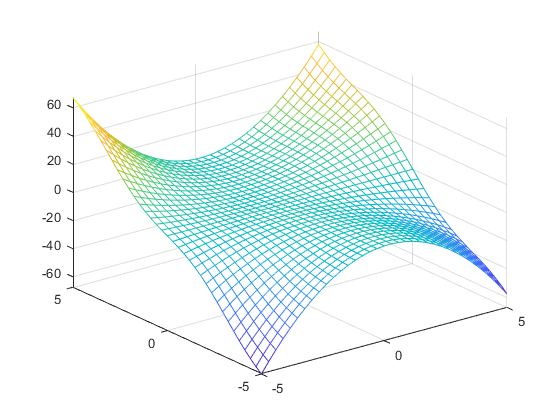

fmesh(U)